output_container_name = "Output";
output_folder_info = dir(output_container_name);
valid_choice_lambda = @(x) {~strcmp(x.name,".") && ~strcmp(x.name,"..") && x.isdir};
what = cell2mat(arrayfun(valid_choice_lambda, output_folder_info));
output_folder_choices = arrayfun(@(x) {x.name}, output_folder_info(what));
output_folder_choices = string(output_folder_choices);
output_folder = output_folder_choices(1);

data_files_base_directory = output_container_name + "/" + output_folder;
data_files = dir(data_files_base_directory);
data_files = data_files(logical(cell2mat(arrayfun(@(f) { ~f.isdir && startsWith(string(f.name), "out")}, data_files))));
all_data = cell(1, length(data_files));
warning("off",'MATLAB:table:ModifiedAndSavedVarnames');
for i_data_file=1:length(data_files)
    data_file = data_files(i_data_file);
    this_table = readtable(data_files_base_directory + "/" + data_file.name, FileType="text",Delimiter="\t");
    all_data{i_data_file} = this_table;
end

master_table = vertcat(all_data{:});
disp("Loaded " + height(master_table) + " experiments");

Loaded 1 experiments


master_table.rho = zeros(height(master_table), 1);
master_table.vMean = zeros(height(master_table), 1);
master_table.algorithm = zeros(height(master_table), 1);
for r = 1:height(master_table)
    this_row_vehicles_position_column = table2array(master_table(r,"VehiclesPosition"));
    tokens = regexp(this_row_vehicles_position_column{1}, '(rho)=(\d+)', 'tokens', 'once');
    new_rho = str2double(tokens{1, 2});
    master_table.rho(r) = new_rho;
    tokens = regexp(this_row_vehicles_position_column{1}, '(vMean)=(\d+)', 'tokens', 'once');
    new_vmean = str2double(tokens{1, 2});
    master_table.vMean(r) = new_vmean;
    this_row_cv2x_algorithm_column = table2array(master_table(r,"C_V2XAllocationAlgorithm_Alg_Params_"));
    tokens = regexp(this_row_cv2x_algorithm_column, '(\d+) ', 'tokens', 'once');
    new_algorithm = str2double(tokens{1, 1});
    master_table.algorithm(r) = new_algorithm;
end

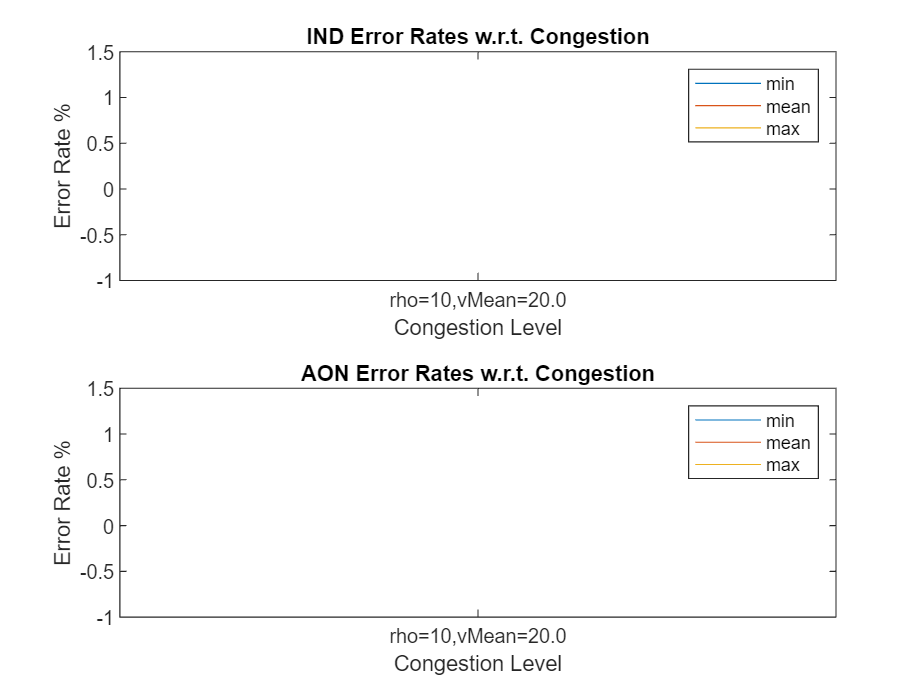

algorithm_choice = "autonomous";
if strcmp(algorithm_choice, "autonomous")
    inspect_table = master_table(master_table.algorithm == 18,:);
else
    centralised_rows = master_table(master_table.algorithm == 2,:);
    if strcmp(algorithm_choice, "centralised_accurate")
        accurate_rows = master_table(strcmp(master_table.Sim_PosError_Tupdate_neighborsSelection_Mvicinity_,'1.0,0.100000,false,-'), :);
        inspect_table = intersect(centralised_rows, accurate_rows);
    elseif strcmp(algorithm_choice, "centralised_inaccurate")
        inaccurate_rows = master_table(strcmp(master_table.Sim_PosError_Tupdate_neighborsSelection_Mvicinity_,'10.0,0.100000,false,-'), :);
        inspect_table = intersect(centralised_rows, inaccurate_rows);
    end
end
traffic_conditions_table = unique(inspect_table(:, ["rho", "vMean"]));
row_to_string = @(rho, vMean) sprintf("rho=%d,vMean=%.1f", rho, vMean);
traffic_conditions_string_array = table2array(rowfun(row_to_string, traffic_conditions_table));
traffic_conditions_groupings = findgroups(inspect_table(:, ["rho", "vMean"]));

min_ind_error_rate = splitapply(@min, inspect_table.ErrorRateIND, traffic_conditions_groupings);
mean_ind_error_rate = splitapply(@mean, inspect_table.ErrorRateIND, traffic_conditions_groupings);
max_ind_error_rate = splitapply(@max, inspect_table.ErrorRateIND, traffic_conditions_groupings);
ind_error_rate_table = table((1:length(traffic_conditions_string_array))',min_ind_error_rate, mean_ind_error_rate, max_ind_error_rate, 'VariableNames', {'congestion_level', 'min','mean','max'});


min_aon_error_rate = splitapply(@min, inspect_table.ErrorRateAON, traffic_conditions_groupings);
mean_aon_error_rate = splitapply(@mean, inspect_table.ErrorRateAON, traffic_conditions_groupings);
max_aon_error_rate = splitapply(@max, inspect_table.ErrorRateAON, traffic_conditions_groupings);
aon_error_rate_table = table((1:length(traffic_conditions_string_array))',min_aon_error_rate, mean_aon_error_rate, max_aon_error_rate, 'VariableNames', {'congestion_level', 'min','mean','max'});

tiledlayout(2, 1);
ax1 = nexttile;
plot(ax1, ind_error_rate_table, ["min" "mean" "max"]);
title('IND Error Rates w.r.t. Congestion')
ylabel('Error Rate %');
xlabel('Congestion Level')
xticks(1:length(traffic_conditions_string_array));
xticklabels(traffic_conditions_string_array');
legend;
ax2 = nexttile;
plot(ax2, aon_error_rate_table, ["min" "mean" "max"]);
title('AON Error Rates w.r.t. Congestion')
ylabel('Error Rate %');
xlabel('Congestion Level')
xticks(1:length(traffic_conditions_string_array));
xticklabels(traffic_conditions_string_array');
legend;